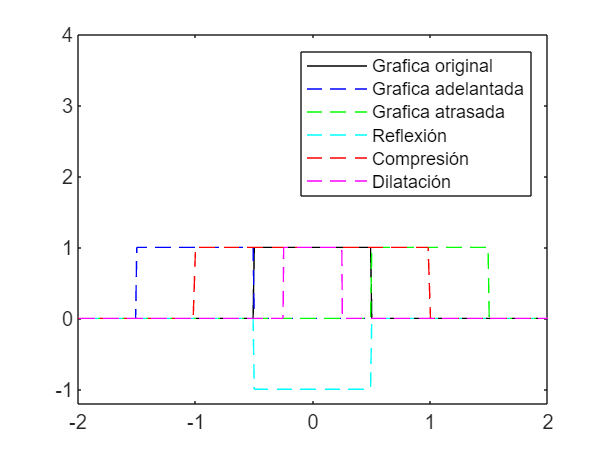

% Crear un vector de tiempo
t = -10:0.01:10;

% función u(t + 1/2) - u(t - 1/2)
plus_half = zeros(size(t));
minus_half = zeros(size(t));

for i = 1:length(t)
    if t(i) >= -0.5
        plus_half(i) = 1;
    end
    if t(i) >= 0.5
        minus_half(i) = 1;
    end
end

result = plus_half - minus_half;

% Graficas 
figure;
title('Función Delta de Dirac');
xlabel('Tiempo');
ylabel('\delta(t)');

% Graficar la función delta(t) original
plot(t, result, "k", 'DisplayName', 'Grafica original');
axis([-2 2 -1.2 4]);

% Graficar la función delta(t) adelantada
hold on
plot(t-1, result, "--b", 'DisplayName', 'Grafica adelantada');

% Graficar la función delta(t) atrasada
plot(t+1, result, "--g", 'DisplayName', 'Grafica atrasada');

% Graficar la función delta(t) reflejada
plot(t, -result, "--c", 'DisplayName', 'Reflexión');

% Graficar la función delta(t) comprimida
plot(t*2, result, "--r", 'DisplayName', 'Compresión');

% Graficar la función delta(t) dilatada
plot(t/2, result, "--m", 'DisplayName', 'Dilatación');

legend;